# Differential expression analysis for scRNASeq Data

**Author**: Scott Campit

## Summary

This notebook incorporates scRNASeq data to constraint-based metabolic models. The base metabolic model is RECON1.

clear all
initCobraToolbox;



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2020
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.25.1).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu

changeCobraSolver('gurobi');

 > changeCobraSolver: Solver gurobi is not installed.


## Bulk scRNASeq DGE

First, we'll model significant genes across time points for multiple cells. This is essentially a bulk analysis by combining different cell types together and finding which genes are up- or downregulated at different time points. 

Up- and downregulated genes were determined by fitting natural splines across time points and taking p-values from LOESS covariates, as performed in Cook & Vanderhyden, 2020.

filepath = '~/Data/scRNASeq/GSE147405/mappedGSE147405.xlsx';
sheet = 'All'

sheet = 'All'

df = readcell(filepath, 'Sheet', sheet)

df = 12809×5 cell array
    {'rownames(map)'}    {'map'      }    {'8hr'        }    {'1day'      }    {'3day'      }
    {'FO538757'     }    {1×1 missing}    {[    -0.0203]}    {[   -0.0195]}    {[   -0.0431]}
    {'AP006222'     }    {1×1 missing}    {[     0.0122]}    {[    0.0348]}    {[1.2095e-04]}
    {'RP11-206L10'  }    {1×1 missing}    {[    -0.0191]}    {[   -0.0420]}    {[   -0.0245]}
    {'LINC00115'    }    {'79854'    }    {[    -0.0184]}    {[   -0.0996]}    {[   -0.0552]}
    {'FAM41C'       }    {'284593'   }    {[    -0.0188]}    {[2.9506e-04]}    {[    0.0163]}
    {'RP11-54O7'    }    {1×1 missing}    {[-4.1582e-04]}    {[    0.0073]}    {[   -0.0176]}
    {'SAMD11'       }    {'148398'   }    {[     0.0396]}    {[    0.0231]}    {[    0.0101]}
    {'NOC2L'        }    {'26155'    }    {[    -0.0870]}    {[   -0.1440]}    {[   -0.0831]}
    {'KLHL17'       }    {'339451'   }    {[     0.0038]}    {[    0.0441]}    {[    0.0374]}
    {'PLEKHN1'      }    {'84069'   

First, we'll get a string vector of the entrez IDs in the scRNASeq dataset.

entrez = string(df(:, 2));

Then we'll load RECON1 and get the intersection between the data and RECON1 genes.

load ~/Data/Reconstructions/RECON1/recon1.mat
[~, ia, ib] = intersect(entrez, recon1.geneEntrezID)

ia =        11340
       11356
        3708
        6070
         542
        2785
        4819
        8513
        2790
        2336


ib =          285
        1484
         766
         264
         981
         374
          77
         354
         773
        1252


We'll also get the gene symbols, and finally the intersection of entrez genes in RECON1 and the dataset.

symbol = recon1.geneRefSeq(ib);

symbol = 968×1 cell array
    {'DGKB'      }
    {'SLC12A1'   }
    {'IDH2'      }
    {'ADSL'      }
    {'P4HA1'     }
    {'ENO3'      }
    {'PDE10A'    }
    {'DUT'       }
    {'IDH3G'     }
    {'AUH'       }
    {'INPP5J'    }
    {'AK2'       }
    {'GBA'       }
    {'CPS1'      }
    {'PEMT'      }
    {'AGL'       }
    {'ALDOB'     }
    {'FH'        }
    {'CTPS2'     }
    {'GGPS1'     }
    {'ALDOA'     }
    {'SLC35A1'   }
    {'ST6GALNAC2'}
    {'ATP6V1E2'  }
    {'AMPD2'     }
    {'ATP5J2'    }
    {'IP6K1'     }
    {'HAGH'      }
    {'HIBADH'    }
    {'PCYT1B'    }


entrez = entrez(ia)

entrez = 968×1 string array
    "100"
    "10005"
    "10007"
    "10020"
    "10026"
    "10057"
    "10165"
    "10166"
    "10195"
    "10201"
    "10229"
    "10257"
    "10312"
    "10327"
    "10331"
    "10380"
    "10390"
    "1040"
    "10400"
    "10402"
    "10423"
    "10554"
    "10555"
    "10558"
    "10559"
    "10560"
    "10587"
    "10588"
    "10606"
    "10610"


Next, we'll get the GAM coefficients. Note that the distribution of the data is normal.

data = cell2mat(df(ia, 3:5))

data =    -0.0524    0.0945    0.0247
    0.0315    0.0121   -0.0114
   -0.0081   -0.0193   -0.0015
    0.3606    0.4092    0.3614
    0.0241   -0.0140    0.0413
   -0.0366   -0.0285   -0.0243
    0.1350    0.1241    0.0470
    0.1177    0.0221    0.1161
   -0.0085   -0.0183   -0.0145
   -0.2577   -0.1188   -0.2528


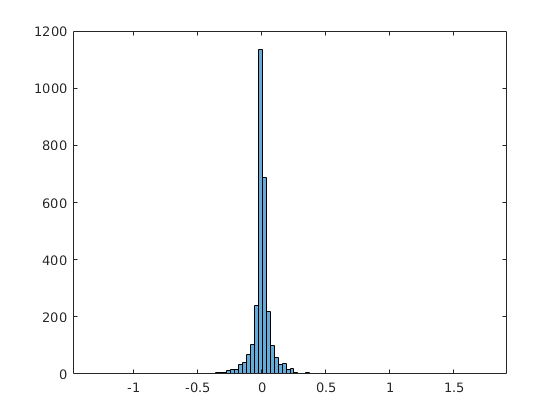

histogram(data, 100)

To distinguish between up and downregulated genes, I simply got the genes that are in the upper and lower quartiles

qnt = quantile(data, [0.25, 0.75], 'all')

qnt =    -0.0170
    0.0206


for i = 1:size(data, 2)
    scDE{i}.up = entrez(data(:, i) > qnt(2));
    scDE{i}.down = entrez(data(:, i) < qnt(1));
end

savepath = '~/Analysis/EMT/scDE.mat';
save(savepath)

## Individual cell scRNASeq DGE